% Filenames
filenames1 = {'02-23-2016_18_23_25'
'02-23-2016_18_22_35'
'02-23-2016_18_21_45'
'02-23-2016_18_20_55'
'02-23-2016_18_20_05'
'02-23-2016_18_19_15'
'02-23-2016_18_18_25'
'02-23-2016_18_17_36'
'02-23-2016_18_16_46'
'02-23-2016_18_15_56'
'02-23-2016_18_15_06'
'02-23-2016_18_14_16'
'02-23-2016_18_13_26'
'02-23-2016_18_12_37'
'02-23-2016_18_11_47'
'02-23-2016_18_10_57'
'02-23-2016_18_09_17'
'02-23-2016_18_08_27'
'02-23-2016_18_05_58'
'02-23-2016_18_05_08'
'02-23-2016_18_04_18'
'02-23-2016_18_03_28'
'02-23-2016_18_02_38'
'02-23-2016_18_01_48'
'02-23-2016_18_00_58'
'02-23-2016_18_00_09'
'02-23-2016_17_59_19'
'02-23-2016_17_58_29'
'02-23-2016_17_55_20'
'02-23-2016_17_54_30'
'02-23-2016_17_53_40'
'02-23-2016_17_52_50'
'02-23-2016_17_52_00'
'02-23-2016_17_51_10'
'02-23-2016_17_48_10'
'02-23-2016_17_47_21'
'02-23-2016_17_46_31'
'02-23-2016_17_45_41'}; % 144 278
filenames2 = {}; % 
filenames3={}; % 

filenames = filenames1;


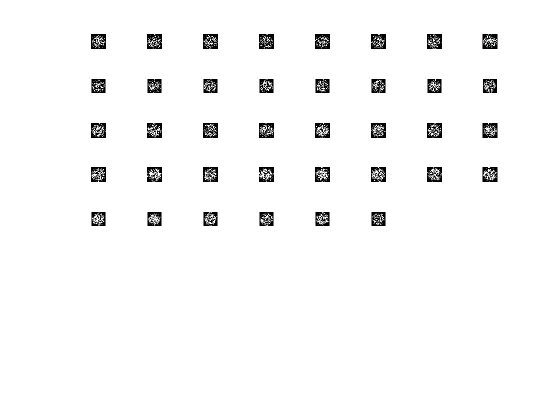

% Load data
data = cell(size(filenames));
atomno = zeros(size(data));
for i = 1:length(data)
    data{i} = imagedata(filenames{i},'crop',{'ellipse',144,278,63,63},'bg',{'avg',10},'plot',{0},'Nsat',3760*5/10);
    atomno(i) = sum(sum(getfield(data{i},'od2')));
end

%% Visualize data
figure;
for i = 1:min(8^2,length(filenames))
    subplot(8,8,i);
    imshow(getfield(data{i},'od2'),[0 1.5]); set(gca,'YDir','normal');
end


clearvars i ans

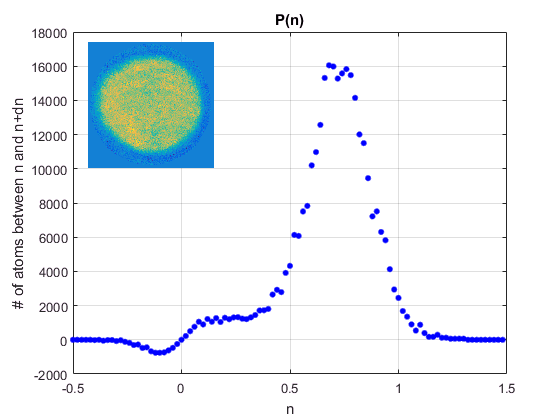

%% P(n) of average
average_od = getfield(data{1},'od2');
for i = 2:length(data), average_od = average_od + getfield(data{i},'od2'); end
average_od = average_od / length(data);
dn_i = 0.02;
n_i_edges = (-0.5:dn_i:1.5)' - dn_i/2;
[n_i,P_n] = extract_Pn(average_od,'plot',1,'plot_nxy_pos',[0.12 0.6 0.3 0.3],'n_i',n_i_edges);

clearvars i dn_i

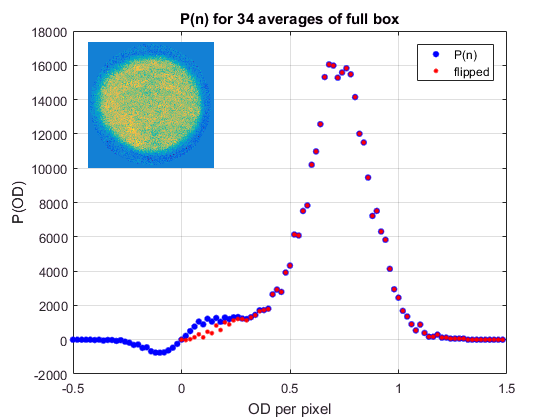

% Folding
ind = find(n_i > -1e-15,1);
P_n_bg = P_n; P_n_bg(ind+1:2*ind-1) = P_n(ind+1:2*ind-1) + flipud(P_n(1:ind-1));
figure;
plot(n_i,P_n,'b.','MarkerSize',15); hold on;
plot(n_i(ind:end),P_n_bg(ind:end),'r.','MarkerSize',10); 
grid on; title('P(n) for 34 averages of full box'); xlabel('OD per pixel'); ylabel('P(OD)');  legend({'P(n)','flipped'}); hold off; 
axes('Position',[0.12 0.6 0.3 0.3]); imagesc(average_od); axis off; axis image;

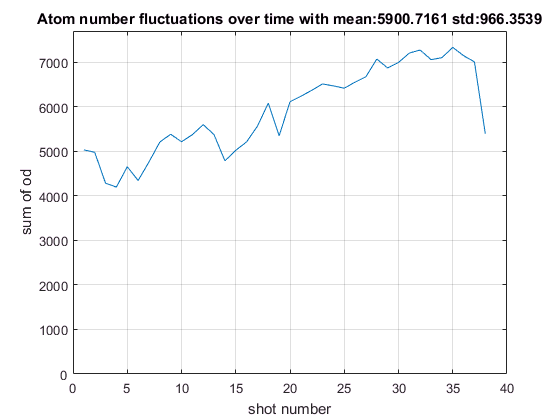

%% Atom number fluctuations
figure; plot(atomno); ylim([0,1.05*max(atomno)]);
grid on; xlabel('shot number'); ylabel('sum of od'); title(['Atom number fluctuations over time with mean:',num2str(mean(atomno)),' std:',num2str(std(atomno))]);

%% 90% atoms within 5% of peak density
P_n_norm = P_n / sum(P_n);
range = 25;
[~,index] = max(P_n);
peak_frac = sum(P_n_norm(index-range:index+range))

peak_frac = 0.9959

peak_n = n_i(index);
range_n = n_i(index+range) - n_i(index)

range_n = 0.5000

(range_n)/peak_n*100

ans = 73.5294